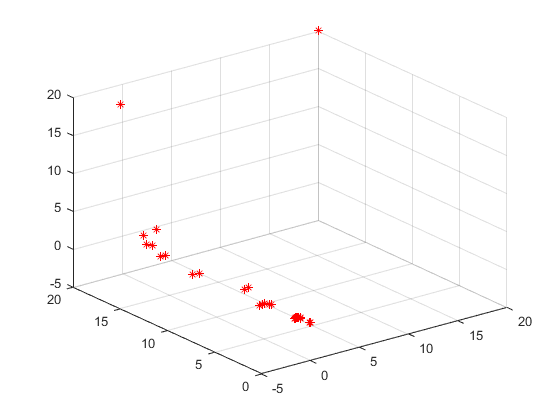

clear
close all
hold off

%HACER ANIMACIÓN DE TODO ESTO

%Vamos a representar cómo se mueve el centro de la formación

N=6; %Número de robots (a partir de N=6 buena aproximación)
iteration=500; %Número de iteraciones
step_size=0.5;
D=1; %Radio de la formación
S=10^-4*[100,1,1;1,1,0;1,0,10]; %Matriz
c0=[20;20;20]; %Posición del centro inicial (initial guess)
r0=[0 0 0]'; %Centro de contaminación
w0=1; %Movimiento circular de un radián por segundo
k=1.1;
c1=10^-4;
c2=0.1; %Parámetros para el line search

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(3,N,iteration);

i=1;

while mod_rc>0.001
    grad_sum=0;
    if i==500
        break
    end
    
    %Aproximación del gradiente en el centro    
    grad_centr(:,i)=gradient_point_3D(c(:,i),t(i),N,D,S,w0);
    
    %Dirección de descenso
    p(:,i)=-grad_centr(:,i);
        %Aplicación del método del gradiente ascendente
    alpha1=0.5;
    steplengthParam=[c1,c2,alpha1,k];
    alpha(i)=alpha_strongWolfe3D(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0);
    c(:,i+1)=c(:,i)+alpha(i)*p(:,i);
        %Hay un nuevo centro alrededor del cual se tienen que poner los robots
    c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
    mod_r_c(i)=norm(c0-r0);
    mod_rc=mod_r_c(i);
    i=i+1;
end
%Representación del centro
plot3(c(1,:),c(2,:),c(3,:),'*r')
grid on
hold off

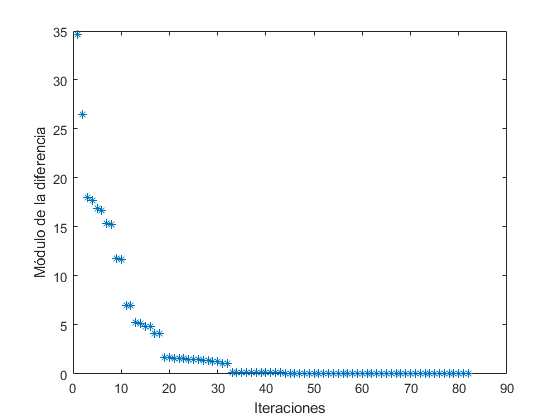

plot(1:length(mod_r_c),mod_r_c,"*")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")


%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 7.1736e-04

c0

c0 = 	1.0e+-3 *

    0.0741
    0.7123
    0.0421


iteraciones=length(mod_r_c)

iteraciones = 82